% Caso k2=1.33
clc
Wn2 = 10^4/47;
Wn = sqrt(Wn2);
xi = -log(20/100)/sqrt(pi^2 + log(20/100)^2);

numT = Wn2;
denT = [1 2*xi*Wn Wn2];

T = tf(numT,denT)


T =
 
         212.8
  --------------------
  s^2 + 13.3 s + 212.8
 
Continuous-time transfer function.



% Solo ponemos la matriz A
f = @(t,X) [X(2); -Wn2*X(1)-2*xi*Wn*X(2)]

f = function_handle with value:
    @(t,X)[X(2);-Wn2*X(1)-2*xi*Wn*X(2)]


x1 = linspace(-.1,.1,10);
x2 = linspace(-1,2,10);

[x,y] = meshgrid(x1,x2);

u = zeros(size(x));
v = zeros(size(x));

t=0;
for i=1:numel(x)
    Xprime = f(t,[x(i),y(i)]);
    u(i) = Xprime(1);
    v(i) = Xprime(2);
end



% quiver(-x,y+1,u,v,'r'); figure(gcf)
% xlabel('x2')
% ylabel('x1')
% % ylim([-5 5])
% % xlim([-.5 .5])
% axis tight;

%% Cargo Simulación
simu = readtable('Simulaciones\stepXY.txt');

tsim = simu{:,1}; 
x2sim = simu{:,2};
x1sim = simu{:,3};

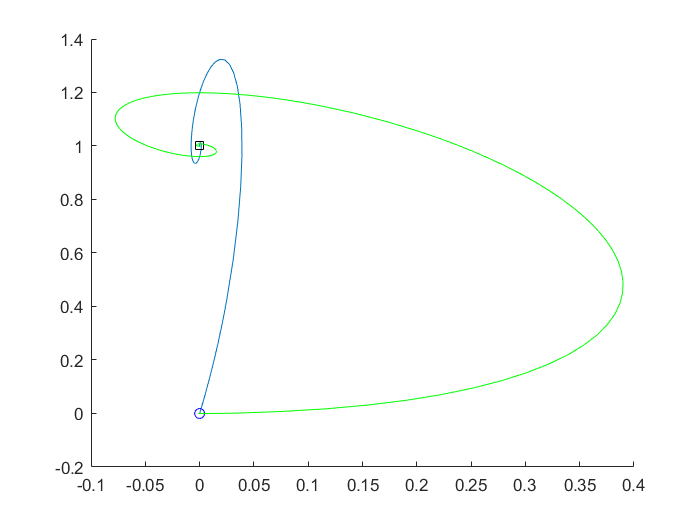

figure(gcf);
hold on
for x20 = [-1]
    [ts,ys] = ode45(f,[0,50],[0;x20]);
    ys(:,1) = -ys(:, 1);
    plot(ys(:,1),ys(:,2) + 1)
    plot(ys(1,1),ys(1,2) + 1,'bo') % starting point
    plot(ys(end,1),ys(end,2) + 1,'ks') % ending point
end

plot(x2sim, x1sim, 'g')

hold off